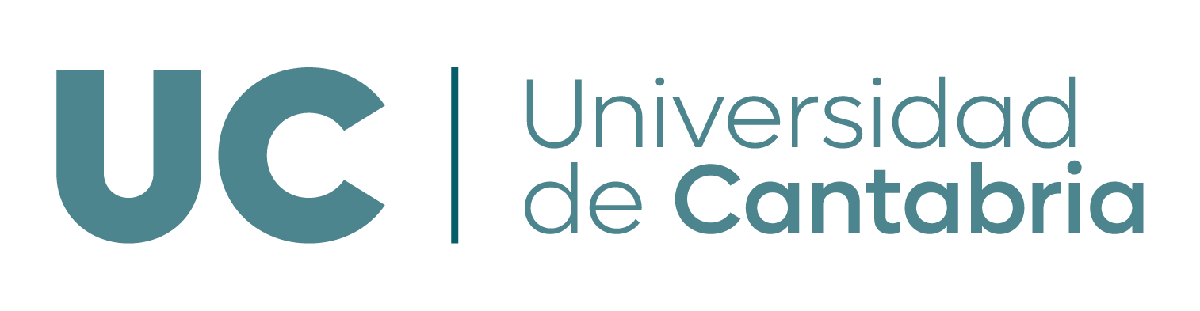

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# ** Guion MATLAB: Endormismos y Diagonalización **

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Cálculo de autovalores y autovectores

- Diagonalización de endomorfismos

**Funciones de MATLAB utilizadas en este guion: **` eig , eye,  diag`

En este guion utilizaremos el siguiente ejemplo de endormorfismo en $ \mathbb{R}^3 $


$$\mathit{f}: \mathbb{R}^3 \longrightarrow  \mathbb{R}^3 \\
(x,y,z) \leadsto (3x-3z, 3y+9z, -3z) $$


Comenzaremos por definir la matriz estándar asociada al endomorfismo:

A = [3 0 -3; 0 3 9; 0 0 -3];  % matriz estándar de f
n=3%dimensión del dominio y codominio 

## **1. Cálculo de autovalores y autovectores.**

### Paso 1: Hallar autovalores 

Para hallar los **autovalores** de $f$ (o $A$), podemos recurrir a la función *eig, *a la cuál le pasaremos como argumento de entrada la matriz cuadrada de la cual queremos hallar los autovalores. La función eig nos devuelve las raices del polinomio característico $p(\lambda)$, obtenido al imponer  $p(\lambda)=det(A-\lambda I)=0$

autoval = eig(A)

En este caso al tratarse de un endomorfismo en  $ \mathbb{R}^3 $ el polinomio característico tiene 3 raices: $\lambda=3$ (doble) y $\lambda=-3$ (doble). Puesto que ambas son números reales, se trata de autovalores del endomorfismo.

**Nota:** ojo `eig` nos devuelve las  $n$ raices (reales o complejas). Puesto que estamos en $ \mathbb{R}^n$, los autovalores serán únicamente aquellas raíces reales, luego deberemos quedarnos únicamente con las raices reales.

### Paso 2: Hallar autovectores asociados a cada autovalor

Una vez tenemos los autovalores de $f$ (o $A$), procedamos a obtener los **autovectores** mediante la resolución de la ecuación $(A-\lambda_i I)\vec{v}=\vec{0}$. Deberemos resolver este sistema homogéneo (compatible indeterminado) para cada uno de los distintos autovalores obtenidos. 

Esto nos permitirá obtener el subespacio propio $V_3$ del autovalor $\lambda=3$y el subespacio propio $V_{-3}$ del autovalor $\lambda=-3$ . 

En concreto, el subespacio propio $V_3$ esta formado por los vectores que verifican $A\vec{v}=3\vec{v}$, o lo que es lo mismo  $(A-3 I)\vec{v}=\vec{0}$

Hallamos el **subespacio propio **$\mathbb{V_3}$ , es decir, el subespacio propio asociado al autovalor $\lambda=3$ (doble). De antemano sabemos que al tener multiplicidad algebraica 2, luego la multiplicidad geométrica podrá ser 1 o 2. Recordemos además que la multiplicidad geométrica, dimensión del subespacio propio, es como mucho igual a la algebraica: $1 \leq \dim(V_\lambda) \leq m(\lambda)
$

n-rank(A-3*eye(n))%multiplicidad geométrica-> número de parametros libres sist. homogéneo 
% base del subespacio propio asociado al autovalor 3 
baseV3 = null(A - 3*eye(3), 'r')  % dim(V3)=2=m(3)

Al obtener una base de $V_3=<(1 ,0 ,0), (0 ,0 ,1)>$ con dos vectores,  la dimensión del subespacio $V_3$  es igual a 2. Luego la multiplicidad geométrica también, $dim(V_3)=2$.

**Comprobación**. Comprobemos que efectivamente los vectores de la base de $V_3$ son autovectores con $\lambda=3$, es decir que 


$$\left(\begin{array}{ccc}
     3 & 0 & -3\\  
     0 & 3 & 9\\  
     0 & 0 & -3\end{array}\right)\left(\begin{array}{ccc}
     1\\  
     0 \\  
     0 \end{array}\right)=3\left(\begin{array}{ccc}
     1\\  
     0 \\  
     0 \end{array}\right)
\quad
y 
\quad

\left(\begin{array}{ccc}
     3 & 0 & -3\\  
     0 & 3 & 9\\  
     0 & 0 & -3\end{array}\right)\left(\begin{array}{ccc}
     0\\  
     1 \\  
     0 \end{array}\right)=3\left(\begin{array}{ccc}
     0\\  
     1 \\  
     0 \end{array}\right)
\quad
\leftrightarrow
\quad
\left(\begin{array}{ccc}
     3 & 0 & -3\\  
     0 & 3 & 9\\  
     0 & 0 & -3\end{array}\right)\left(\begin{array}{cc}
     1& 0 \\  
     0 & 1 \\  
     0&0 \end{array}\right)=3\left(\begin{array}{ccc}
    1& 0 \\  
     0 & 1 \\   
     0 & 0 \end{array}\right)

$$
      

A*baseV3-3*baseV3

Además, por ser $V_3$ un espacio vectorial, la combinación lineal de dos vectores $\vec{u} $y  $\vec{v} $cualesquiera de $V_3$ pertenecerá también a $V_3$, y por tanto será autovector de $A$con $\lambda=3$. Escojamos por ejemplo la siguiente combinación lineal:

w=3*baseV3(:,1)-5*baseV3(:,2)%una combinación lineal cualquiera de los vectores basede V3

y comprobemos que w  es autovector con $\lambda=3$, es decir, $A \vec{w}=3 \vec{w}$

A*w-3*w

Por último, hallamos el **subespacio propio** $V_{-3}$ asociado al autovalor $\lambda=-3$. De antemano al ser multiplicidad algebraica simple,$m(-3)=1$, sabemos que la multiplicidad geométrica será 1.

% base subespacio propio asociado al autovalor -3 
baseVmenos3 = null(A +3*eye(3), 'r')  % dim(Vmenos3)=1=m(-3)


$$V_{-3}=<(1/2 ,-3/2 ,1)>$$


**Comprobación**. Comprobemos que efectivamente los vectores de la base de $V_{-3}$ son autovectores con $\lambda=-3$, es decir que 


$$\left(\begin{array}{ccc}
     3 & 0 & -3\\  
     0 & 3 & 9\\  
     0 & 0 & -3\end{array}\right)\left(\begin{array}{ccc}
     \frac{1}{2}\\  
     -\frac{3}{2}\ \\  
     1 \end{array}\right)=-3\left(\begin{array}{ccc}
       \frac{1}{2}\\  
     -\frac{3}{2}\ \\
     1\end{array}\right)

$$
 

A*baseVmenos3+3*baseVmenos3

## 2. Diagonalización de un endomorfismo

 Antes de diagonalizar la matriz comprobaremos siempre que el endormorfismo sea diagonalizable. Recordemos que para que un endomorfismo $f$ en $\mathbb{R}^n$sea diagonalizable debemos poder obtener una base de $\mathbb{R}^n$ formada por autovectores de $f$. Para ello, han de cumplirse dos condiciones:

- Todos sus autovalores tienen que ser reales (necesitamos n autovalores contando multiplicidades)

- La dimensión de cada subespacio propio tiene que coincidir con la multiplicidad (algebraica) del autovalor al que está asociado. 

En nuestro ejemplo de endomorfismo en $\mathbb{R}^3$, podemos ver que ambas condiciones se cumplen.

- todas las raices son reales: $\lambda=3 $(doble) $\lambda=-3 $  

- la multiplicidad geométrica de cada autovalor coincide con la algebraica: $m(3)=dim(V_3)=3$  y $m(-3)=dim(V_{-3})=1$

Por tanto, $f$ será diagonalizable. Como sabemos, diagonalizar $f$ consiste en encontrar una matriz diagonal $D$ y otra matriz regular $P$ tales que $A=PDP^{-1}$, o lo que es lo mismo $D=P^{-1}AP$. 

La diagonal de $D$ estará formada por los autovalores de $f$ y $P$ contendrá en sus columnas una base de $\mathbb{R}^n$ formada de autovectores de $f$ . Ha de respetarse el mismo orden al colocar los valores propios en la diagonal de $D$ y los correspondientes vectores propios en las columnas de $P$.  

D = diag(autoval)
P = [baseVmenos3 baseV3 ]

Podemos comprobar fácilmente que, efectivamente, al juntar las bases de los subespacios propios obtenemos una base de $\mathbb{R}^3$:

rank(P)  % los tres vectores son l.i. -> forman base de R³

Comprobamos que las matrices $D$ y $P$ que hemos obtenido son las correctas $A=PDP^{-1}$ 

A - P*D*inv(P)

## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.